(h)  Repeat (a) for the training data set given in P1-data2.txt. 	

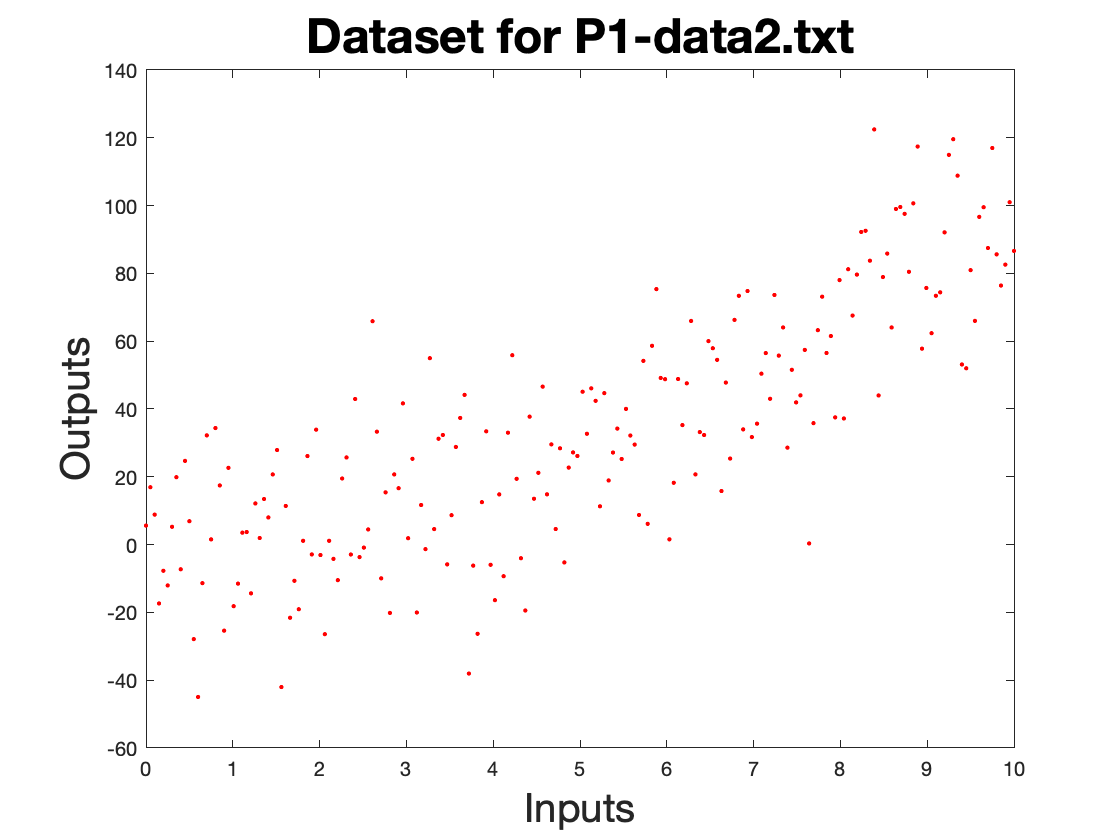

clear all;
close all;
filename ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data2.txt';
delimiter = ',';

A = importdata(filename);
inputs= A(:,1);
outputs = A(:,2);
plot(inputs,outputs,'r.');
xlabel('Inputs',"FontSize",20);
ylabel('Outputs',"FontSize",20);
title('Dataset for P1-data2.txt',"FontSize",24);

(i)  Fit the learning parameters (β0, β1 and β2) to the training data set contained in the file P1- data2.txt using the following hypothesis function:h(x) = β0 + β1x + β2x2, where x is the input variable. For the gradient decent algorithm, initialize all the learning parame- ters to 0, and use proper values for both the learning rate and the total number of iterations based on your observations from parts (c)-(e). Plot the hypothesis function along with the training data set. Clearly state your choices for the learning rate and the number of iterations. 		

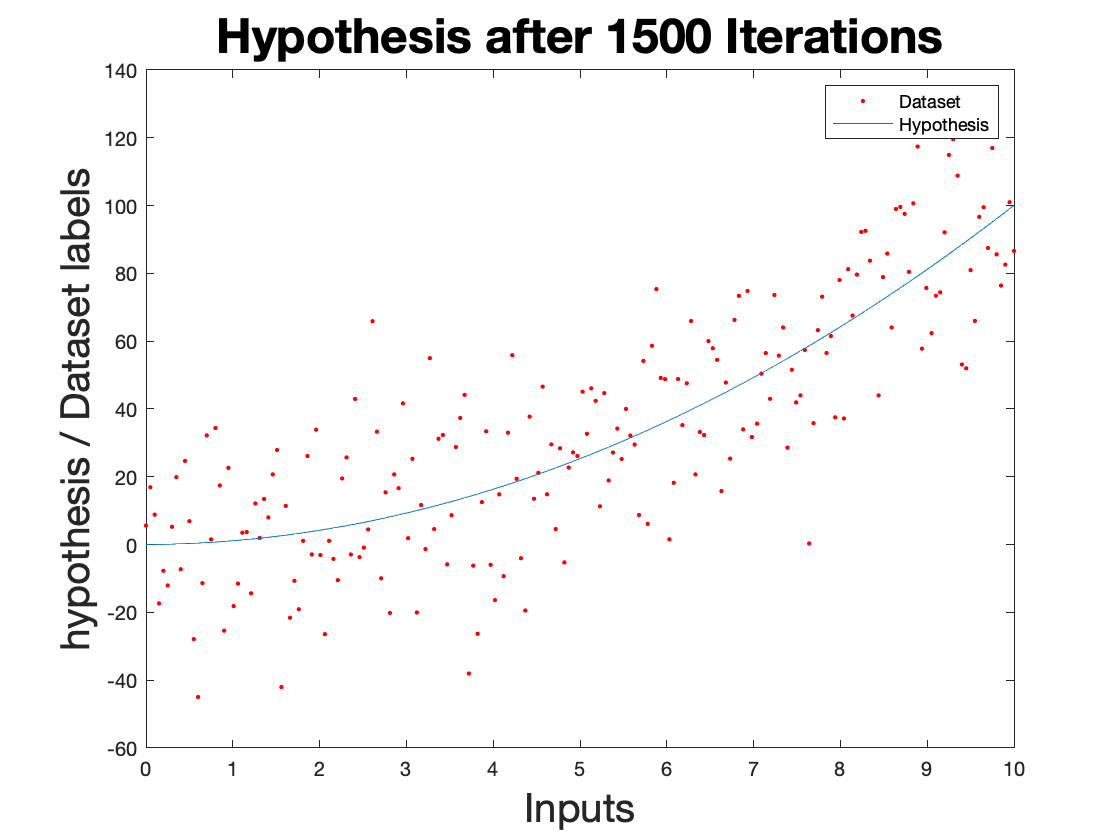

B_0=0;
B_1=0;
B_2=0;
Beta = [B_0 B_1 B_2];
iterations = 20;
learn_rate = 10^-6; 
Beta_update = zeros(length(inputs),3);
input_1x =[ones(1,length(inputs)); transpose(inputs)];
input_2x =[ones(1,length(inputs)); transpose(inputs); transpose(inputs).^2];
y_caps = zeros(1,length(inputs));
for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs)
        
        y_caps(i) = B_0 + B_1 * inputs(i) +  B_2 * inputs(i)* inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate *error);
        B_1 = B_1 - (learn_rate *error*inputs(i));
        B_2 = B_2- (learn_rate *error*inputs(i)*inputs(i));
        Beta_update(i,:) = [B_0 B_1 B_2];
        
        
    end
    

end
hyp = Beta_update(length(inputs),:) * input_2x;
plot(inputs,outputs,'r.');
hold on;
plot(inputs,hyp);
title('Hypothesis after 1500 Iterations',"FontSize",24);
ylabel('hypothesis / Dataset labels',"FontSize",20);
xlabel('Inputs',"FontSize",20);
legend({'Dataset','Hypothesis'});
hold off;

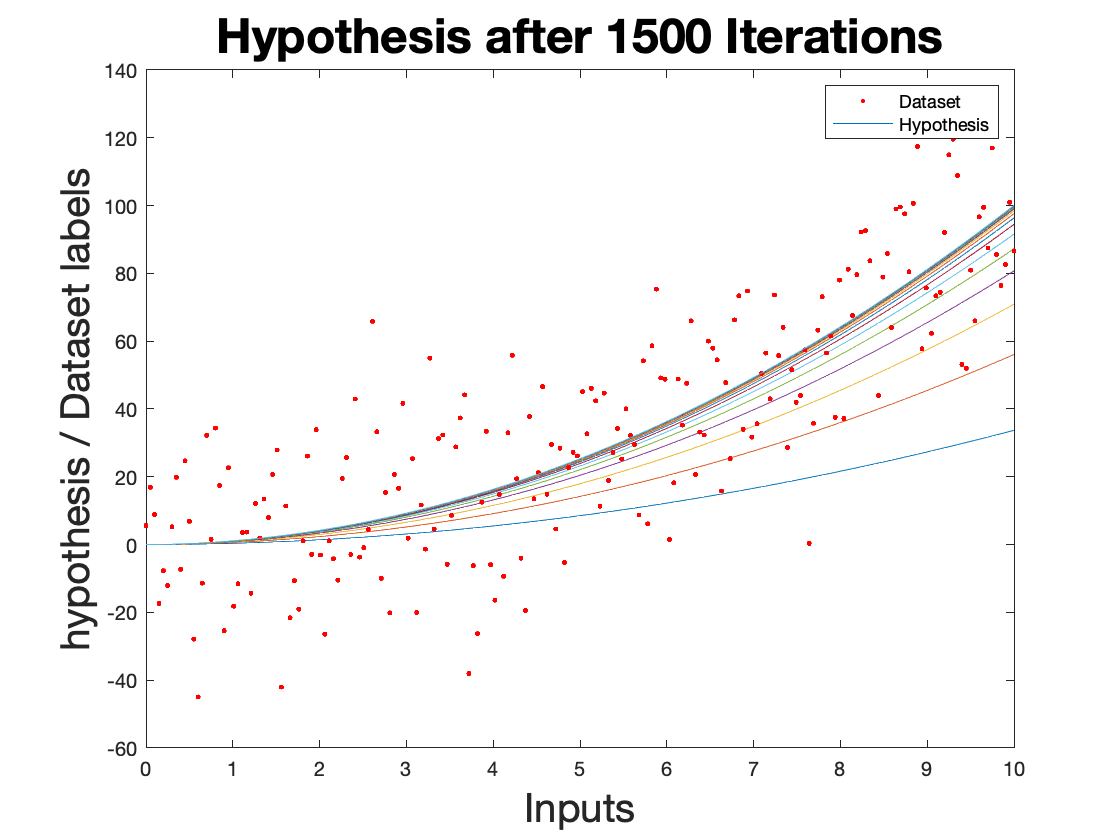


B_0=0;
B_1=0;
B_2=0;
Beta = [B_0 B_1 B_2];
for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(inputs)
        
        y_caps(i) = B_0 + B_1 * inputs(i) +  B_2 * inputs(i)* inputs(i);
        error= y_caps(i) - outputs(i);
        B_0 = B_0 - (learn_rate *error);
        B_1 = B_1 - (learn_rate *error*inputs(i));
        B_2 = B_2- (learn_rate *error*inputs(i)*inputs(i));
        Beta_update(i,:) = [B_0 B_1 B_2];
        
        
    end
hyp = Beta_update(length(inputs),:) * input_2x;
plot(inputs,outputs,'r.');
hold on;
plot(inputs,hyp);
end
title('Hypothesis after 1500 Iterations',"FontSize",24);
ylabel('hypothesis / Dataset labels',"FontSize",20);
xlabel('Inputs',"FontSize",20);
legend({'Dataset','Hypothesis'});

hold off;